clear
clc
close all

syms N_b Omega R c theta C_la C_d rho y dy
assume(N_b>0);
assume(Omega>0);
assume(R>0);
assume(c>0);
assume(theta>0);
assume(C_la>0);
assume(C_d>0);
assume(rho>0);
assume(y>0);
assume(dy>0);

r = y / R ;
dr = dy / R ;



## Assumptions

syms lambda_c lambda_i mu beta betadot psi theta_0 sigma sigma_0
assume(lambda_c>0);
assume(lambda_i>0);
assume(mu>0);
assume(beta>0);
assume(betadot>0);
assume(psi>0);
assume(theta_0>0);
assume(sigma>0);
assume(sigma_0>0);

beta = 0;                                   % Assuming NO blade flapping
betadot = 0;                                % Assuming NO blade dynamics 
mu = 0;                                     % Assuming NO fordward flight
theta = theta_0;                            % Assuming constant pitch
sigma = sigma_0;                            % Assuming constant solidity
arg1 = ( sigma*C_la/16 - lambda_c/2);
arg2 = sigma*C_la*theta*r/8;
lambda_BEMT = sqrt( arg1^2 + arg2 ) - arg1; 
lambda = lambda_BEMT;                       % Assuming BEMT inflow
% lambda = lambda_c + lambda_i;               % Assuming vetical fligth

lambda

$$lambda = \frac{\lambda_{c}}{2}+\sqrt{{\left(\frac{\lambda_{c}}{2}-\frac{C_{\mathrm{la}}\,\sigma_{0}}{16}\right)}^{2}+\frac{C_{\mathrm{la}}\,\sigma_{0}\,\theta_{0}\,y}{8\,R}}-\frac{C_{\mathrm{la}}\,\sigma_{0}}{16}$$


U_T = (Omega*R) * ( r + mu*sin(psi) );
U_P = (Omega*R) * ( lambda + r*betadot/Omega + mu*beta*cos(psi) );
U_R = (Omega*R) * ( mu*cos(psi) );

phi = U_P / U_T;
alpha = theta - phi;                        % sectional angle of attack

q = 0.5*rho*U_T^2;                          % dynamic pressure    
Cl = C_la*(alpha);                          % lift coefficient
dL = q*c*Cl*dy;                             % sectional lift
dD = q*c*C_d*dy;                            % sectional drag

dT = N_b * ( dL );                          % sectional thrust
dQ = N_b * ( phi*dL + dD ) * y;             % sectional torque
dP = dQ * Omega;                            % sectional power

% sectional thrust
dT = simplify(dT)

$$dT = \frac{C_{\mathrm{la}}\,N_{b}\,\Omega^{2}\,c\,\mathrm{dy}\,\rho \,y^{2}\,\left(\theta_{0}-\frac{R\,\left(\frac{\lambda_{c}}{2}+\sqrt{{\left(\frac{\lambda_{c}}{2}-\frac{C_{\mathrm{la}}\,\sigma_{0}}{16}\right)}^{2}+\frac{C_{\mathrm{la}}\,\sigma_{0}\,\theta_{0}\,y}{8\,R}}-\frac{C_{\mathrm{la}}\,\sigma_{0}}{16}\right)}{y}\right)}{2}$$

% sectional power
dP = simplify(dP)

$$dP = \begin{array}{l} N_{b}\,\Omega \,y\,\left(\frac{C_{d}\,\Omega^{2}\,c\,\mathrm{dy}\,\rho \,y^{2}}{2}+\frac{C_{\mathrm{la}}\,\Omega^{2}\,R\,c\,\mathrm{dy}\,\rho \,y\,\left(\theta_{0}-\frac{R\,\sigma_{1}}{y}\right)\,\sigma_{1}}{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\lambda_{c}}{2}+\sqrt{{\left(\frac{\lambda_{c}}{2}-\frac{C_{\mathrm{la}}\,\sigma_{0}}{16}\right)}^{2}+\frac{C_{\mathrm{la}}\,\sigma_{0}\,\theta_{0}\,y}{8\,R}}-\frac{C_{\mathrm{la}}\,\sigma_{0}}{16} \end{array}$$

% Integrate along the blade
T_psi = int(dT, y, 0, R)                    

$$T\_psi = \begin{array}{l} \frac{{C_{\mathrm{la}}}^{2}\,N_{b}\,\Omega^{2}\,R^{3}\,c\,\mathrm{dy}\,\rho \,\sigma_{0}}{64}+\frac{C_{\mathrm{la}}\,N_{b}\,\Omega^{2}\,R\,c\,\mathrm{dy}\,\rho \,\left(\frac{R^{2}\,{\sigma_{1}}^{3/2}\,\left(768\,\sigma_{1}-320\,{\lambda_{c}}^{2}-\sigma_{3}+80\,C_{\mathrm{la}}\,\lambda_{c}\,\sigma_{0}\right)}{\sigma_{2}}-\frac{R^{2}\,{\left(\sigma_{1}+\frac{C_{\mathrm{la}}\,\sigma_{0}\,\theta_{0}}{8}\right)}^{3/2}\,\left(768\,\sigma_{1}-320\,{\lambda_{c}}^{2}-\sigma_{3}+80\,C_{\mathrm{la}}\,\lambda_{c}\,\sigma_{0}+96\,C_{\mathrm{la}}\,\sigma_{0}\,\theta_{0}\right)}{\sigma_{2}}\right)}{2}-\frac{C_{\mathrm{la}}\,N_{b}\,\Omega^{2}\,R^{3}\,c\,\mathrm{dy}\,\lambda_{c}\,\rho }{8}+\frac{C_{\mathrm{la}}\,N_{b}\,\Omega^{2}\,R^{3}\,c\,\mathrm{dy}\,\rho \,\theta_{0}}{6}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\lambda_{c}}{2}-\frac{C_{\mathrm{la}}\,\sigma_{0}}{16}\right)}^{2}\\ \sigma_{2}=30\,{C_{\mathrm{la}}}^{2}\,{\sigma_{0}}^{2}\,{\theta_{0}}^{2}\\ \sigma_{3}=5\,{C_{\mathrm{la}}}^{2}\,{\sigma_{0}}^{2} \end{array}$$

% Integrate along the blade
P_psi = int(dP, y, 0, R)     

$$P\_psi = \begin{array}{l} \frac{N_{b}\,\Omega^{3}\,R^{4}\,c\,\mathrm{dy}\,\rho \,\left(573440\,{\lambda_{c}}^{4}\,{\sigma_{1}}^{3/2}-2752512\,{\lambda_{c}}^{2}\,{\sigma_{1}}^{5/2}-819200\,{\lambda_{c}}^{4}\,\sqrt{{\sigma_{2}}^{6}}+2752512\,{\lambda_{c}}^{2}\,\sqrt{{\sigma_{2}}^{10}}+3932160\,{\sigma_{1}}^{7/2}-1680\,{C_{\mathrm{la}}}^{4}\,{\sigma_{0}}^{4}\,{\theta_{0}}^{3}-105\,{C_{\mathrm{la}}}^{5}\,{\sigma_{0}}^{5}\,{\theta_{0}}^{2}+43008\,{C_{\mathrm{la}}}^{2}\,{\sigma_{0}}^{2}\,{\sigma_{1}}^{5/2}-420\,{C_{\mathrm{la}}}^{4}\,{\sigma_{0}}^{4}\,{\sigma_{1}}^{3/2}-43008\,{C_{\mathrm{la}}}^{2}\,{\sigma_{0}}^{2}\,\sqrt{{\sigma_{2}}^{10}}+360\,{C_{\mathrm{la}}}^{4}\,{\sigma_{0}}^{4}\,\sqrt{{\sigma_{2}}^{6}}+4480\,{C_{\mathrm{la}}}^{3}\,\lambda_{c}\,{\sigma_{0}}^{3}\,{\theta_{0}}^{3}+1680\,{C_{\mathrm{la}}}^{4}\,\lambda_{c}\,{\sigma_{0}}^{4}\,{\theta_{0}}^{2}+8960\,{C_{\mathrm{la}}}^{3}\,\lambda_{c}\,{\sigma_{0}}^{3}\,{\sigma_{1}}^{3/2}-7040\,{C_{\mathrm{la}}}^{3}\,\lambda_{c}\,{\sigma_{0}}^{3}\,\sqrt{{\sigma_{2}}^{6}}-6720\,{C_{\mathrm{la}}}^{3}\,{\lambda_{c}}^{2}\,{\sigma_{0}}^{3}\,{\theta_{0}}^{2}-53760\,{C_{\mathrm{la}}}^{2}\,{\lambda_{c}}^{2}\,{\sigma_{0}}^{2}\,{\sigma_{1}}^{3/2}+30720\,{C_{\mathrm{la}}}^{2}\,{\lambda_{c}}^{2}\,{\sigma_{0}}^{2}\,\sqrt{{\sigma_{2}}^{6}}+122880\,C_{\mathrm{la}}\,{\lambda_{c}}^{3}\,\sigma_{0}\,\sqrt{{\sigma_{2}}^{6}}+6720\,C_{d}\,{C_{\mathrm{la}}}^{2}\,{\sigma_{0}}^{3}\,{\theta_{0}}^{2}\right)}{53760\,{C_{\mathrm{la}}}^{2}\,{\sigma_{0}}^{3}\,{\theta_{0}}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\sigma_{2}}^{2}+\frac{C_{\mathrm{la}}\,\sigma_{0}\,\theta_{0}}{8}\\ \sigma_{2}=\frac{\lambda_{c}}{2}-\frac{C_{\mathrm{la}}\,\sigma_{0}}{16} \end{array}$$

% Integrate along the azimuth
dy = 1;
T_psi = subs(T_psi);
P_psi = subs(P_psi);
T_tot= int(T_psi, psi, 0, 2*pi)             

$$T\_tot = \begin{array}{l} \frac{\pi \,{C_{\mathrm{la}}}^{2}\,N_{b}\,\Omega^{2}\,R^{3}\,c\,\rho \,\sigma_{0}}{32}+\pi \,C_{\mathrm{la}}\,N_{b}\,\Omega^{2}\,R\,c\,\rho \,\left(\frac{R^{2}\,{\sigma_{1}}^{3/2}\,\left(768\,\sigma_{1}-320\,{\lambda_{c}}^{2}-\sigma_{3}+80\,C_{\mathrm{la}}\,\lambda_{c}\,\sigma_{0}\right)}{\sigma_{2}}-\frac{R^{2}\,{\left(\sigma_{1}+\frac{C_{\mathrm{la}}\,\sigma_{0}\,\theta_{0}}{8}\right)}^{3/2}\,\left(768\,\sigma_{1}-320\,{\lambda_{c}}^{2}-\sigma_{3}+80\,C_{\mathrm{la}}\,\lambda_{c}\,\sigma_{0}+96\,C_{\mathrm{la}}\,\sigma_{0}\,\theta_{0}\right)}{\sigma_{2}}\right)-\frac{\pi \,C_{\mathrm{la}}\,N_{b}\,\Omega^{2}\,R^{3}\,c\,\lambda_{c}\,\rho }{4}+\frac{\pi \,C_{\mathrm{la}}\,N_{b}\,\Omega^{2}\,R^{3}\,c\,\rho \,\theta_{0}}{3}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\lambda_{c}}{2}-\frac{C_{\mathrm{la}}\,\sigma_{0}}{16}\right)}^{2}\\ \sigma_{2}=30\,{C_{\mathrm{la}}}^{2}\,{\sigma_{0}}^{2}\,{\theta_{0}}^{2}\\ \sigma_{3}=5\,{C_{\mathrm{la}}}^{2}\,{\sigma_{0}}^{2} \end{array}$$

% Integrate along the azimuth
P_tot = int(P_psi, psi, 0, 2*pi)    

$$P\_tot = \begin{array}{l} \frac{\pi \,N_{b}\,\Omega^{3}\,R^{4}\,c\,\rho \,\left(573440\,{\lambda_{c}}^{4}\,{\sigma_{1}}^{3/2}-2752512\,{\lambda_{c}}^{2}\,{\sigma_{1}}^{5/2}-819200\,{\lambda_{c}}^{4}\,\sqrt{{\sigma_{2}}^{6}}+2752512\,{\lambda_{c}}^{2}\,\sqrt{{\sigma_{2}}^{10}}+3932160\,{\sigma_{1}}^{7/2}-1680\,{C_{\mathrm{la}}}^{4}\,{\sigma_{0}}^{4}\,{\theta_{0}}^{3}-105\,{C_{\mathrm{la}}}^{5}\,{\sigma_{0}}^{5}\,{\theta_{0}}^{2}+43008\,{C_{\mathrm{la}}}^{2}\,{\sigma_{0}}^{2}\,{\sigma_{1}}^{5/2}-420\,{C_{\mathrm{la}}}^{4}\,{\sigma_{0}}^{4}\,{\sigma_{1}}^{3/2}-43008\,{C_{\mathrm{la}}}^{2}\,{\sigma_{0}}^{2}\,\sqrt{{\sigma_{2}}^{10}}+360\,{C_{\mathrm{la}}}^{4}\,{\sigma_{0}}^{4}\,\sqrt{{\sigma_{2}}^{6}}+4480\,{C_{\mathrm{la}}}^{3}\,\lambda_{c}\,{\sigma_{0}}^{3}\,{\theta_{0}}^{3}+1680\,{C_{\mathrm{la}}}^{4}\,\lambda_{c}\,{\sigma_{0}}^{4}\,{\theta_{0}}^{2}+8960\,{C_{\mathrm{la}}}^{3}\,\lambda_{c}\,{\sigma_{0}}^{3}\,{\sigma_{1}}^{3/2}-7040\,{C_{\mathrm{la}}}^{3}\,\lambda_{c}\,{\sigma_{0}}^{3}\,\sqrt{{\sigma_{2}}^{6}}-6720\,{C_{\mathrm{la}}}^{3}\,{\lambda_{c}}^{2}\,{\sigma_{0}}^{3}\,{\theta_{0}}^{2}-53760\,{C_{\mathrm{la}}}^{2}\,{\lambda_{c}}^{2}\,{\sigma_{0}}^{2}\,{\sigma_{1}}^{3/2}+30720\,{C_{\mathrm{la}}}^{2}\,{\lambda_{c}}^{2}\,{\sigma_{0}}^{2}\,\sqrt{{\sigma_{2}}^{6}}+122880\,C_{\mathrm{la}}\,{\lambda_{c}}^{3}\,\sigma_{0}\,\sqrt{{\sigma_{2}}^{6}}+6720\,C_{d}\,{C_{\mathrm{la}}}^{2}\,{\sigma_{0}}^{3}\,{\theta_{0}}^{2}\right)}{26880\,{C_{\mathrm{la}}}^{2}\,{\sigma_{0}}^{3}\,{\theta_{0}}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\sigma_{2}}^{2}+\frac{C_{\mathrm{la}}\,\sigma_{0}\,\theta_{0}}{8}\\ \sigma_{2}=\frac{\lambda_{c}}{2}-\frac{C_{\mathrm{la}}\,\sigma_{0}}{16} \end{array}$$

% Normalize to a1
% a1 = subs( ( pi*N_b*rho*c*Omega^2*C_la*R^3 )/6 );
% a1 = subs( ( pi*N_b*rho*c*C_la*R^3 )/6 );
% T_tot = simplify( subs(T_tot / a1) )
% P_tot = simplify( subs(P_tot / a1) )

# Analysis on a 0.25m blade

N_b = 2;
R = 1/4;                    % m
c = 0.1/4;                  % m
rho = 1.225;                % kg/m3
C_la = 2*3.14;
theta_0 = 20*3.14/180;      % rad
C_d = C_la*theta_0 / 10;
sigma_0 = N_b*c*R/(pi*R^2);

T_tot = vpa(eval(subs(T_tot)), 2)

$$T\_tot = \begin{array}{l} 2.4e-3\,\Omega^{2}-4.7e-3\,\Omega^{2}\,\lambda_{c}-0.3\,\Omega^{2}\,\left(0.11\,{\left(\sigma_{1}+0.017\right)}^{3/2}\,\left(32.0\,\lambda_{c}+777.0\,\sigma_{1}-322.0\,{\lambda_{c}}^{2}+13.0\right)-0.11\,{\sigma_{1}}^{3/2}\,\left(32.0\,\lambda_{c}+777.0\,\sigma_{1}-322.0\,{\lambda_{c}}^{2}-0.8\right)\right)\\ \mathrm{where}\\ \sigma_{1}={\left(0.5\,\lambda_{c}-0.025\right)}^{2} \end{array}$$

P_tot = vpa(eval(subs(P_tot)), 2)

$$P\_tot = \begin{array}{l} 2.3e-5\,\Omega^{3}\,\left(17.0\,\lambda_{c}+577.0\,\lambda_{c}\,{\sigma_{2}}^{3/2}-11.0\,{\sigma_{2}}^{3/2}+6.9e+3\,{\sigma_{2}}^{5/2}+3.9e+6\,{\sigma_{2}}^{7/2}-455.0\,\lambda_{c}\,\sigma_{1}-8.6e+3\,{\lambda_{c}}^{2}\,{\sigma_{2}}^{3/2}-2.8e+6\,{\lambda_{c}}^{2}\,{\sigma_{2}}^{5/2}+5.7e+5\,{\lambda_{c}}^{4}\,{\sigma_{2}}^{3/2}+9.2\,\sigma_{1}-6.9e+3\,\sigma_{3}+4.9e+3\,{\lambda_{c}}^{2}\,\sigma_{1}+4.9e+4\,{\lambda_{c}}^{3}\,\sigma_{1}-8.2e+5\,{\lambda_{c}}^{4}\,\sigma_{1}+2.8e+6\,{\lambda_{c}}^{2}\,\sigma_{3}-52.0\,{\lambda_{c}}^{2}-0.13\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\left(0.5\,\lambda_{c}-0.025\right)}^{6}}\\ \sigma_{2}={\left(0.5\,\lambda_{c}-0.025\right)}^{2}+0.017\\ \sigma_{3}=\sqrt{{\left(0.5\,\lambda_{c}-0.025\right)}^{10}} \end{array}$$

## BEMT inflow dependance on climb velocity

% Integrate along the blade
avg_lambda = int(lambda, y, 0, R) / R;
avg_lambda = vpa(eval(subs(avg_lambda)), 2)

$$avg\_lambda = 0.5\,\lambda_{c}+38.0\,{\left({\left(0.5\,\lambda_{c}-0.025\right)}^{2}+0.017\right)}^{3/2}-38.0\,{\left({\left(0.5\,\lambda_{c}-0.025\right)}^{2}\right)}^{3/2}-0.025$$

lambda_c_arr = 0:0.01:0.15;
ns = length(lambda_c_arr);

avg_lambda_arr = zeros(ns, 1);
avg_lambda_i_arr = zeros(ns, 1);
for i = 1:ns
    lc = lambda_c_arr(i); % / (Omega*R);
    avg_lambda_arr(i) = subs(avg_lambda, lambda_c, lc);
    avg_lambda_i_arr(i) = avg_lambda_arr(i) - lc;  
end

lh = avg_lambda_arr(1)

lh = 0.0672

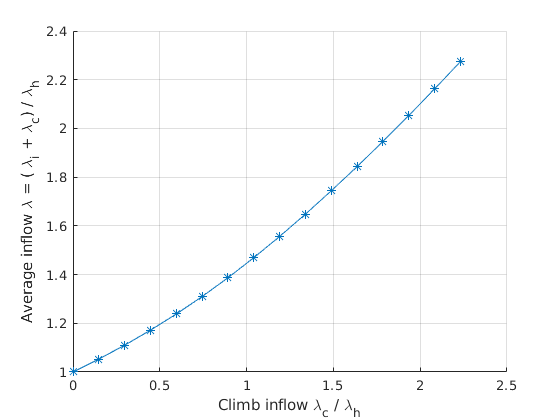

figure;
hold on;
grid on;
plot(lambda_c_arr./lh, avg_lambda_arr./lh, '-*')
% legend('isolation', 'interference')
xlabel('Climb inflow \lambda_c / \lambda_h')
ylabel('Average inflow \lambda = ( \lambda_i + \lambda_c) / \lambda_h')

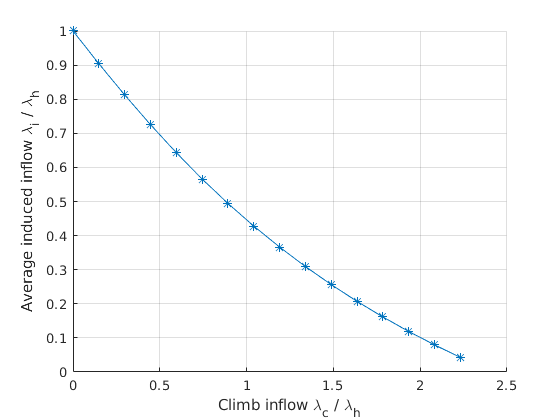


figure;
hold on;
grid on;
plot(lambda_c_arr./lh, avg_lambda_i_arr./lh, '-*')
% legend('isolation', 'interference')
xlabel('Climb inflow \lambda_c / \lambda_h')
ylabel('Average induced inflow \lambda_i / \lambda_h')

## Thrust dependance on climb velocity (at fixed RPM)

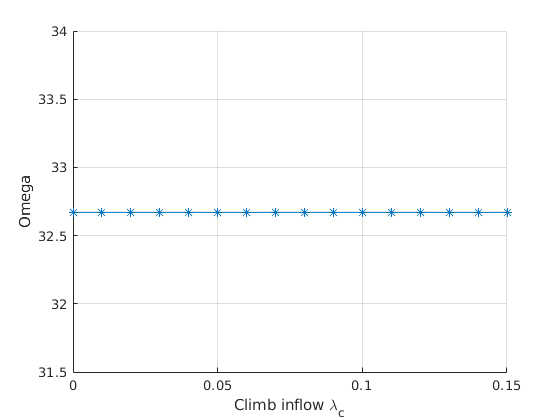

lambda_c_arr = 0:0.01:0.15;
ns = length(lambda_c_arr);

Omega_arr = zeros(ns, 1);
T_arr = zeros(ns, 1);
P_arr = zeros(ns, 1);
for i = 1:ns
    lc = lambda_c_arr(i);
    T_i = subs(T_tot, lambda_c, lc); 
    P_i = subs(P_tot, lambda_c, lc);
        
    Omega_0 = 32.6702;    % Hz
    solx = Omega_0;
    
    Omega_arr(i) = solx;
    T_arr(i) = subs(T_i, Omega, solx); 
    P_arr(i) = subs(P_i, Omega, solx);    
end

figure;
hold on;
grid on;
plot(lambda_c_arr, Omega_arr, '-*')
% legend('isolation', 'interference')
xlabel('Climb inflow \lambda_c')
ylabel('Omega')

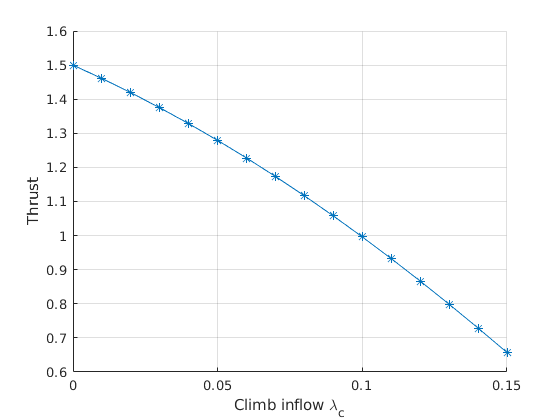

figure;
hold on;
grid on;
plot(lambda_c_arr, T_arr, '-*')
% legend('isolation', 'interference')
xlabel('Climb inflow \lambda_c')
ylabel('Thrust')

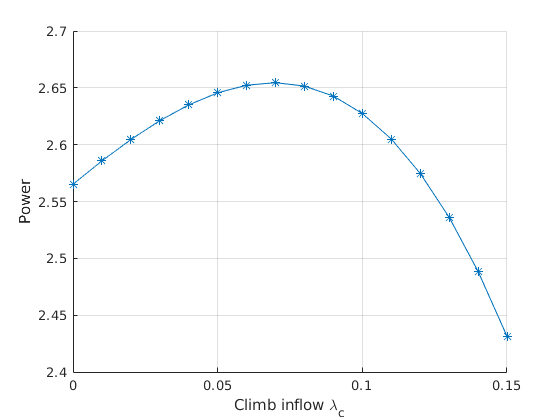

figure;
hold on;
grid on;
plot(lambda_c_arr, P_arr, '-*')
% legend('isolation', 'interference')
xlabel('Climb inflow \lambda_c')
ylabel('Power')

## Power dependance on climb velocity (at fixed Thrust)

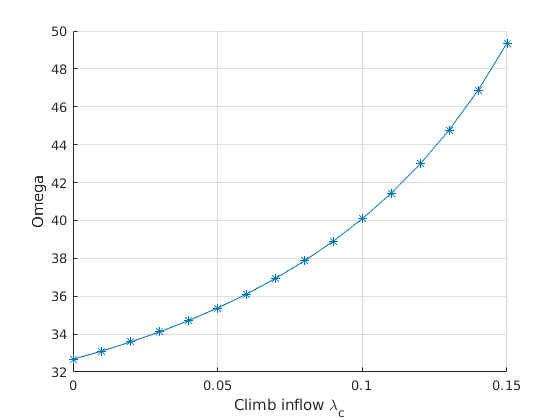

lambda_c_arr = 0:0.01:0.15;
ns = length(lambda_c_arr);

Omega_arr = zeros(ns, 1);
T_arr = zeros(ns, 1);
P_arr = zeros(ns, 1);
for i = 1:ns
    lc = lambda_c_arr(i);
    T_i = subs(T_tot, lambda_c, lc); 
    P_i = subs(P_tot, lambda_c, lc);
        
    T_0 = 1.5;
    [solx, parameters, conditions] = solve(T_i == T_0, Omega, 'ReturnConditions', true);         
    
    Omega_arr(i) = solx;
    T_arr(i) = subs(T_i, Omega, solx); 
    P_arr(i) = subs(P_i, Omega, solx);    
end

figure;
hold on;
grid on;
plot(lambda_c_arr, Omega_arr, '-*')
% legend('isolation', 'interference')
xlabel('Climb inflow \lambda_c')
ylabel('Omega')

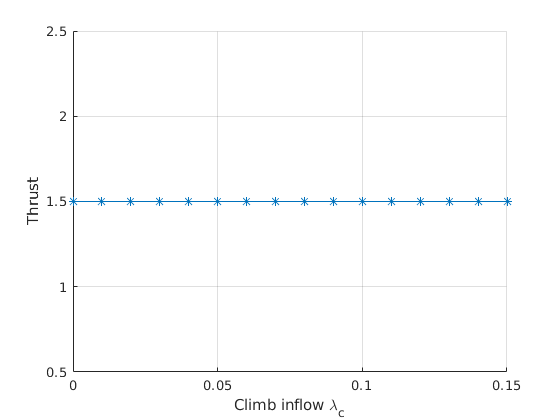

figure;
hold on;
grid on;
plot(lambda_c_arr, T_arr, '-*')
% legend('isolation', 'interference')
xlabel('Climb inflow \lambda_c')
ylabel('Thrust')

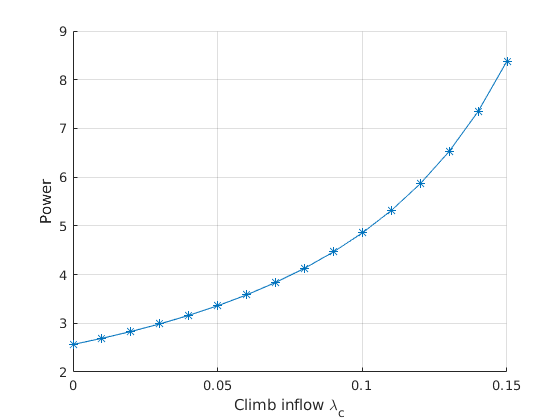

figure;
hold on;
grid on;
plot(lambda_c_arr, P_arr, '-*')
% legend('isolation', 'interference')
xlabel('Climb inflow \lambda_c')
ylabel('Power')